# Scripts Fonctions de transfert

clear;clc;close all;
format shorteng; format compact;


Constantes

Kp = -1;


Définition de la fonction de transfert

num = [1];
den = [1, 2, 1];
sys = tf(num, den)

sys =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



Transformée inverse (besoin d'un addon "Inverse Laplace Transform of Transfer Function Class")

ilaplacetf(sys)

$$ans = t\,{\mathrm{e}}^{-t}$$

## Décomposer en fractions partielles

Utilisé pour faire Laplace inverse

... = r1/p1 + r2/p2 + r3/p3 + k

[r p k] = residue(num, den)

r =      0.0000e+000
     1.0000e+000


p =     -1.0000e+000
    -1.0000e+000


k =
     []


## Esquisser la réponse indicielle

à un saut unité

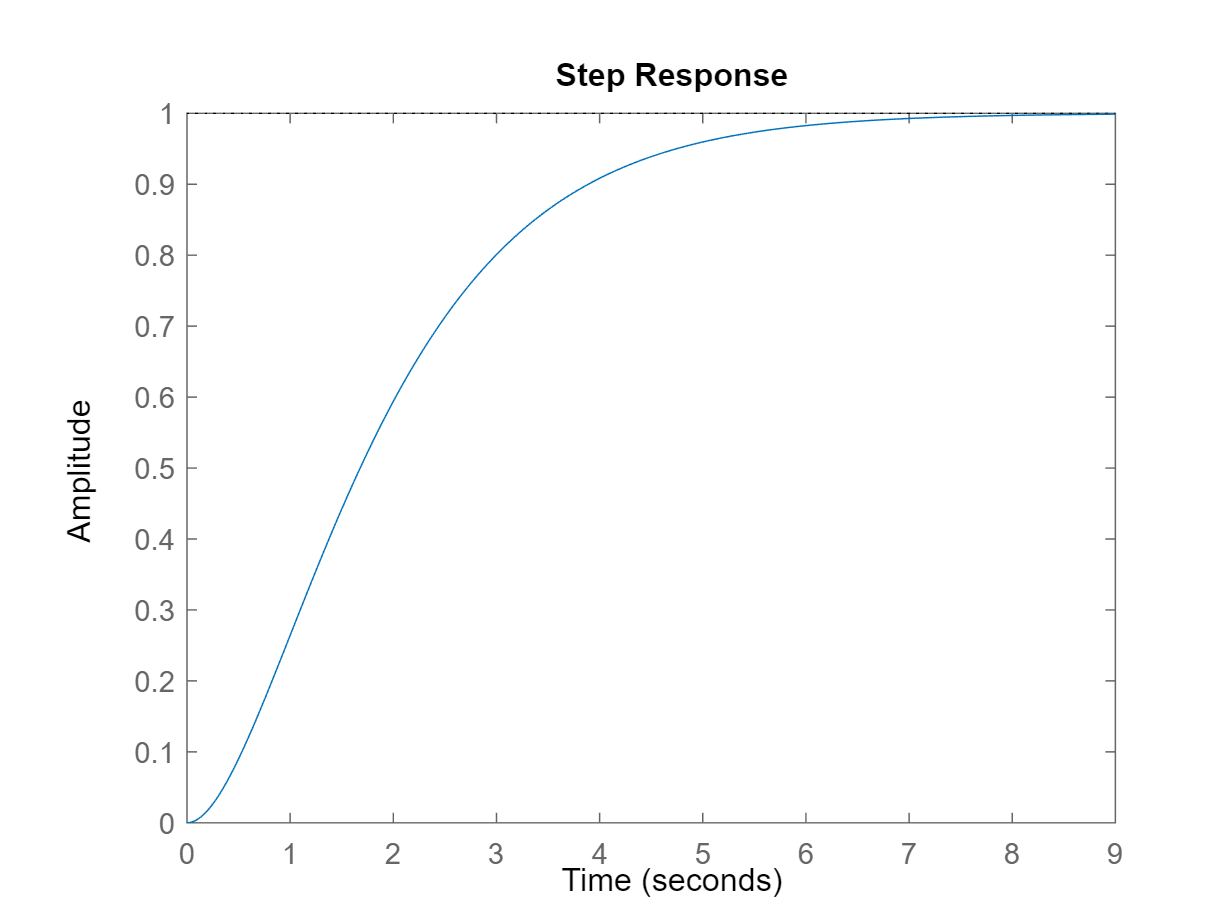

step(sys);

## Esquisser la réponse impulsionnelle

à une impulsion de dirac

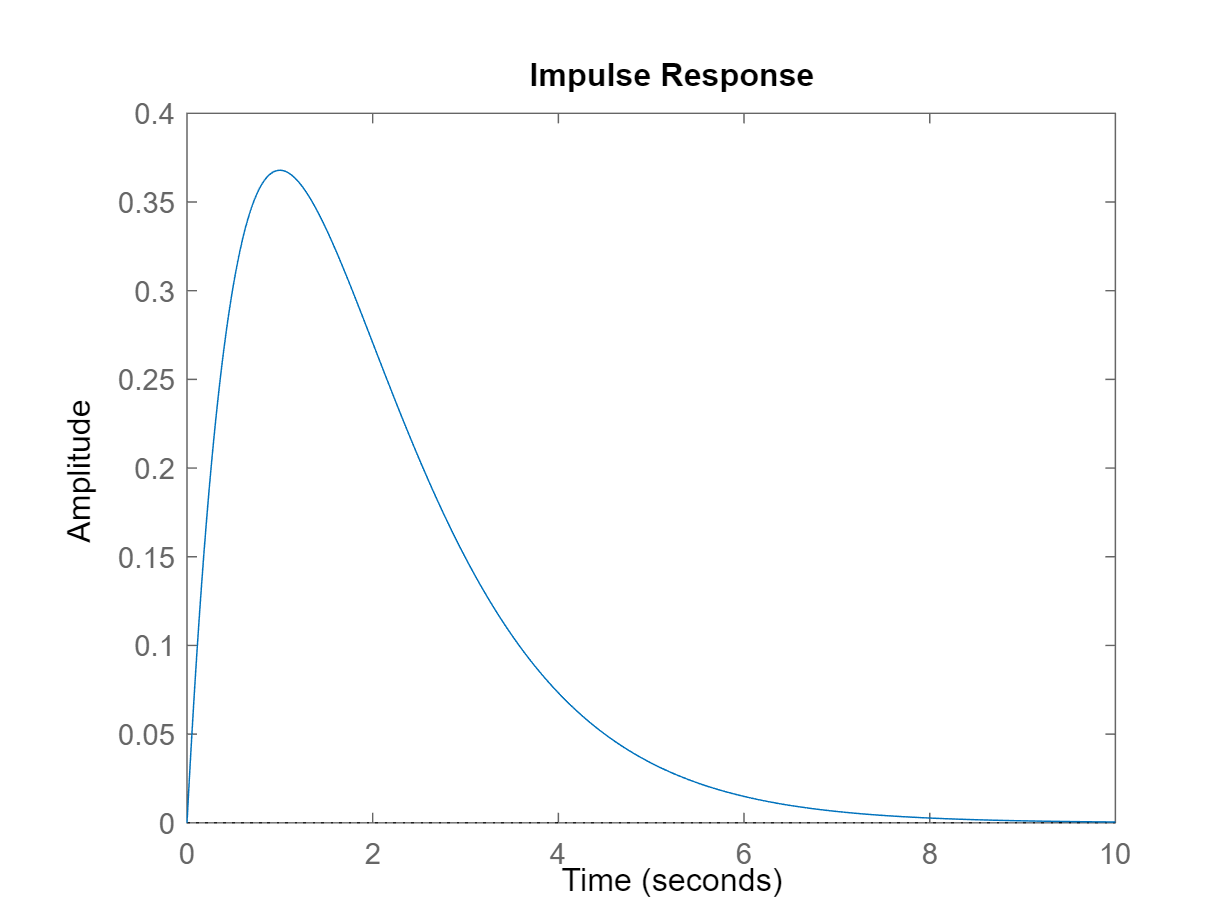

impulse(sys);

## Calculer les pôles

poles = pole(sys)

poles =     -1.0000e+000
    -1.0000e+000


## Pulsation naturelle

Si conjugués complexes

omega_0 = abs(poles(1)) % Norme

omega_0 =      1.0000e+000

Si non conjugués complexes

omega_0 = sqrt(poles(1) * poles(2))

omega_0 =      1.0000e+000

## Facteur d'amortissement

Si conjugués complexes

xi = - real(poles(1)) / omega_0

xi =      1.0000e+000

Si non conjugués complexes

xi = - (poles(1) + poles(2))/(2*omega_0)

xi =      1.0000e+000

## Pulsation de résonnance

Si conjugués complexes

omega_r = abs(imag(poles(1)))

omega_r =      0.0000e+000

Si non conjugués complexes

omega_r = omega_0 * sqrt(1-xi^2)

omega_r =      0.0000e+000